im = im2gray(imread("cat.jpg")); %исходный массив 
n1 = 7; n2 = 17; n3 = 55;
block_1 = ones(n1)/n1^2.; block_2 = ones(n2)/n2^2.; block_3 = ones(n3)/n3^2.;

%первая матрица
gaus_1 = zeros(n1);
for x = 1:1:n1
    for y = 1:1:n1
        gaus_1(x,y) = func(n1,x,y);
    end
end
%вторая матрица
gaus_2 = zeros(n2);
for x = 1:1:n2
    for y = 1:1:n2
        gaus_2(x,y) = func(n2,x,y);
    end
end
%тертья матрица
gaus_3 = zeros(n3);
for x = 1:1:n3
    for y = 1:1:n3
        gaus_3(x,y) = func(n3,x,y);
    end
end
gaus_1 = gaus_1/sum(gaus_1, "all");
gaus_2 = gaus_2/sum(gaus_2, "all");
gaus_3 = gaus_3/sum(gaus_3, "all");


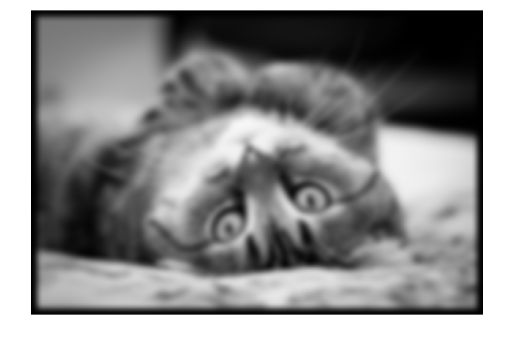

ans1 = cast(conv2(im,gaus_3),"uint8");
ans2 = cast(svert(im,gaus_3),"uint8");
% imwrite(ans1,'C:\LATEX\Fourier_analiz\Fourier_6\2_6conv.png');
% imwrite(ans2,'C:\LATEX\Fourier_analiz\Fourier_6\2_6four.png');
imshow(ans1)

imshow(ans2)

function y = func(n,x,y)
    y = exp((-9/n^2)*((x-(n+1)/2)^2+(y-(n+1)/2)^2));
end

function y = svert(im,m) %передается ядро
    h = height(im); w = width(im); %высота и ширина исходного
    f_im = fftshift(fft2(im, h+height(m)-1,w+width(m)-1)); %образ Фурье для изображения
    f_m = fftshift(fft2(m, h+height(m)-1,w+width(m)-1)); %образ для ядра
    d = f_im.*f_m;
    y = ifft2(ifftshift(d));
end